%this code creates the 3D occpancy map from an open street map using a Lidar simulation. This maps
%is then used to to apply the static path planning algorithims like A* or
%RRT*
close all
close all hidden 
%Create a UAV scenario and set its local origin.
%scene = uavScenario("UpdateRate",200,"StopTime",2,"ReferenceLocation",[46, 42, 0]); 

simTime = 6;    % in seconds
updateRate = 2;  % in Hz
scene = uavScenario("UpdateRate",updateRate,"StopTime",simTime,"ReferenceLocation",[(51.4970+51.5003)/2 (-0.1805-0.1705)/2 0]); % It should be set to within the latitude longitude ranges shown in the verbose output
%Add an inertial frame called MAP to the scenario.
%scene.addInertialFrame("ENU","MAP",trvec2tform([1 0 0])); %why this step ?
xlimits = [-300 300];
ylimits = [-300 300];
altitude = 0;
color = [0.6 0.6 0.6];
addMesh(scene,"terrain",{"gmted2010",xlimits,ylimits},color,Verbose=true)

Importing gmted2010 
Latitude range (degree): [-90 90] 
Longitude range (degree): [-180 180]
UAV Scenario Reference Latitude (degree): 51.4986 
UAV Scenario Reference Longitude (degree): -0.1755


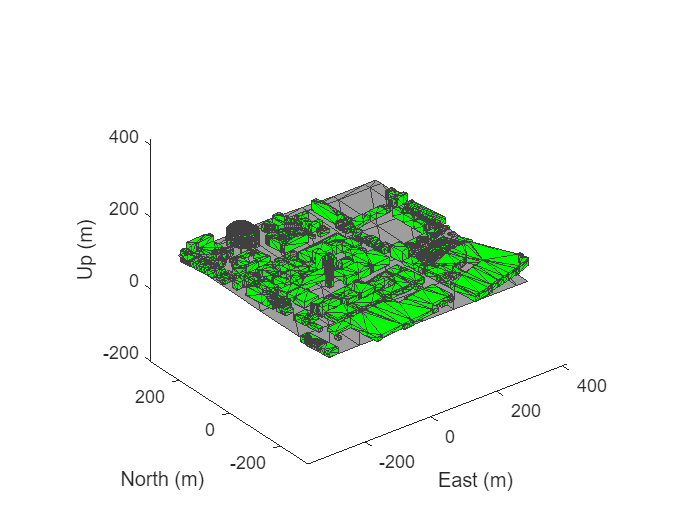

color = [0 1 0];
osmInfo = addMesh(scene,"buildings",{"ICL_map.osm",xlimits,ylimits,"auto"},color,Verbose=true); %"buildings"	{osmFile,xBound,yBound,altitude}
%map is got from : https://www.openstreetmap.org/export#map=17/51.49870/-0.17547
%OSM : OpenStreetMap
figure;
show3D(scene);

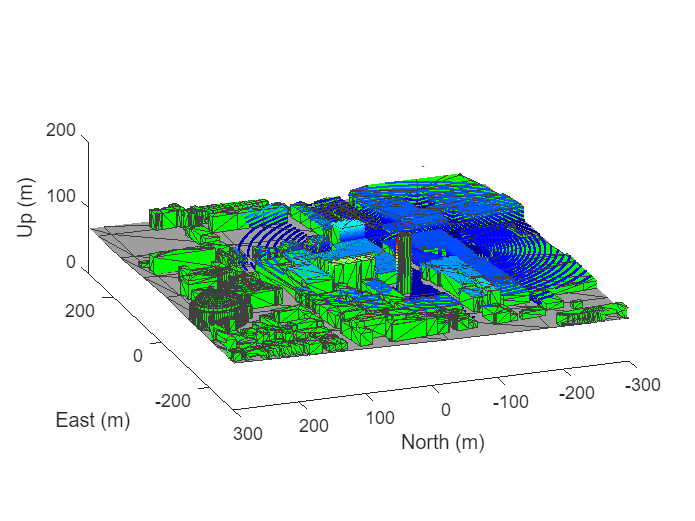

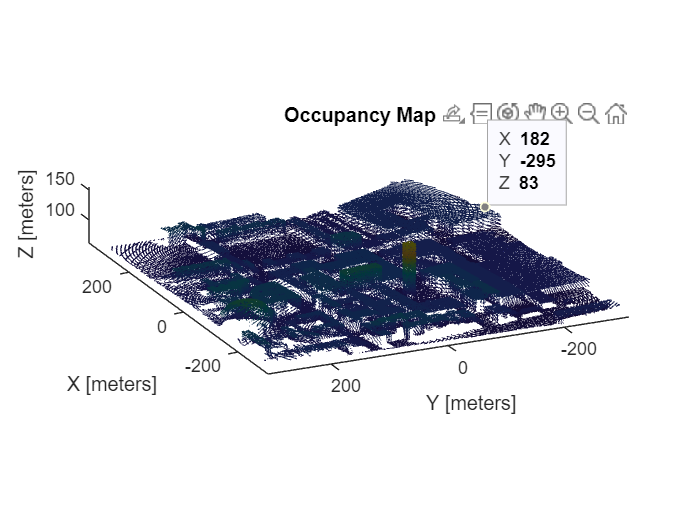

%figure;
%building 3D occupancy map 
% Waypoints 
%%
% 
% x = [-300:300,-300:300]
% 
% y = [-300:300,300:-1:-300];
% z = 100*ones(1,length(y));
% %-200, -200, -300 , 0 , 200, 200, 200,0, -200,
% -200, 0 , 200, 200 , 200, 0, -200,-200,-200,
x = [-200, -200, -200 , 0 , 200, 200, 200,0, -200,-100, -100, -100 , 0 , 100, 100, 100,0, -100];
y = [-200, 0 , 200, 200 , 200, 0, -200,-200,-200,-100, 0 , 100, 100 , 100, 0, -100,-100,-100]; 
z = 200*ones(1,length(x)); 
waypoints = [x' y' z']; 
%Specify the orientation as Euler angles (in radians) and convert the Euler angles to a quaternion:
orientation_eul = [0 0 0];
orientation_quat = quaternion(eul2quat(orientation_eul)); 
orientation_vec = repmat(orientation_quat,length(x),1);
%Specify time vector
 time = 0:(simTime/(length(x)-1)):simTime;
%Generate trajectory from the specified waypoints and orientations using waypointTrajectory system object. Specify the reference frame as 'ENU'. 
trajectory = waypointTrajectory("Waypoints",waypoints,"Orientation",orientation_vec, ...
    "SampleRate",updateRate,"ReferenceFrame","ENU","TimeOfArrival",time); 
%Specify the initial pose of the UAV
initial_pose = [-300 -300 100 1 0 0 0]; 
%Create a uavPlatform object and update the scenario with a mesh of the UAV. 
plat = uavPlatform("UAV",scene,"Trajectory",trajectory,"ReferenceFrame","ENU"); 
updateMesh(plat,"quadrotor",{4},[1 0 0],eye(4)); %updateMesh(platform,type,geometries,color,position,orientation) %geo : "quadrotor"	{scale}
%Introduce a 3D lidar into the scenario using the uavLidarPointCloudGenerator system object. Specify relevant lidar sensor parameters. For example, the lidar in this example has a maximum range of 200 meters, but you can adjust the parameters as needed.
lidarmodel = uavLidarPointCloudGenerator("AzimuthResolution",0.1, ...
    "ElevationLimits",[-90 0],"ElevationResolution",1.25, ...
    "MaxRange",300,"UpdateRate",2,"HasOrganizedOutput",true);

lidar = uavSensor("Lidar",plat,lidarmodel,"MountingLocation",[0 0 -1],"MountingAngles",[0 0 0]); 

%Simulate Mapping Flight And Map Building
[ax,plotFrames] = show3D(scene);
xlim(xlimits);
ylim(ylimits);
zlim([0 200]);
view([-115 20]); 
axis equal 
hold on

colormap('jet');
ptc = pointCloud(nan(1,1,3));
scatterplot = scatter3(nan,nan,nan,1,[0.3020 0.7451 0.9333],...
    "Parent",plotFrames.UAV.Lidar);
scatterplot.XDataSource = "reshape(ptc.Location(:,:,1), [], 1)";
scatterplot.YDataSource = "reshape(ptc.Location(:,:,2), [], 1)";
scatterplot.ZDataSource = "reshape(ptc.Location(:,:,3), [], 1)";
scatterplot.CDataSource = "reshape(ptc.Location(:,:,3), [], 1) - min(reshape(ptc.Location(:,:,3), [], 1))";
hold off; 

lidarSampleTime = [];
pt = cell(1,((updateRate*simTime) +1)); 
ptOut = cell(1,((updateRate*simTime) +1)); 
%Create an occupancy map for a more efficient way to store the point cloud data. Use a minimum resolution of 1 cell per meter.
map3D = occupancyMap3D(1);
%Simulate the mapping flight in the scenario. Store lidar sensor readings for each simulation step in a cell array after removing invalid points. Insert point clouds into the map using the insertPointCloud function. Ensure that the pose vector accounts for sensor offset. 
setup(scene); 

ptIdx = 0;
while scene.IsRunning
    ptIdx = ptIdx + 1;
    % Read the simulated lidar data from the scenario
    [isUpdated,lidarSampleTime,pt{ptIdx}] = read(lidar);

    if isUpdated
        % Get Lidar sensor's pose relative to ENU reference frame.
        sensorPose = getTransform(scene.TransformTree, "ENU","UAV/Lidar",lidarSampleTime);
        % Process the simulated Lidar pointcloud.
        ptc = pt{ptIdx};
        ptOut{ptIdx} = removeInvalidPoints(pt{ptIdx});
        % Construct the occupancy map using Lidar readings.
        insertPointCloud(map3D,[sensorPose(1:3,4)' tform2quat(sensorPose)],ptOut{ptIdx},500);

        figure(1)
        show3D(scene,"Time",lidarSampleTime,"FastUpdate",true,"Parent",ax);
        xlim(xlimits);
        ylim(ylimits);
        zlim([0 200]);
        view([-110 20]);
        
        refreshdata
        drawnow limitrate
    end
    
    %Show map building real time 
    figure(2)
    show(map3D);
    view([-115 20]);
    axis equal 
    
    advance(scene);
    updateSensors(scene); 
    
end

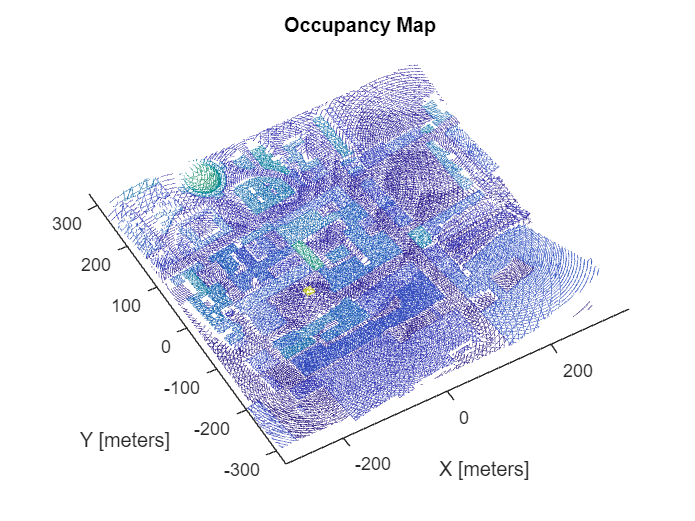

figure
show(map3D);